Nbits = 1e6;
in = randi([0, 1], [Nbits, 1])*2-1;

Transmitter

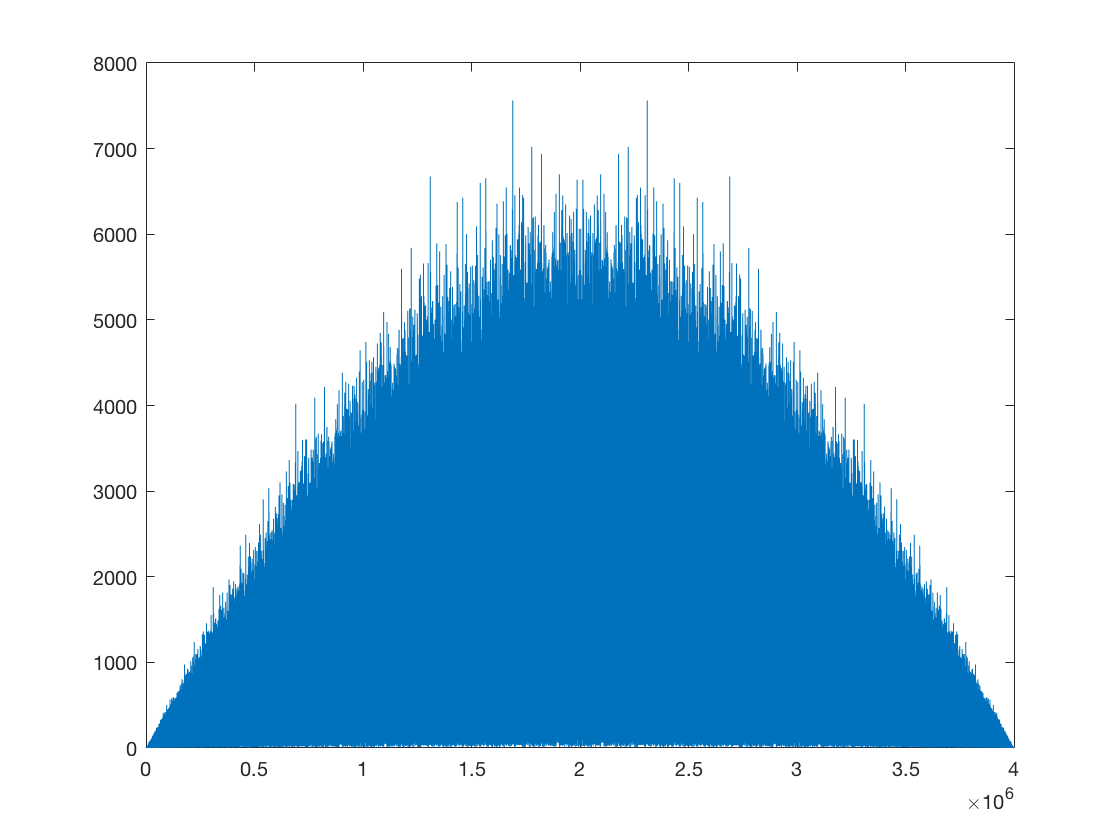

k = 2;
SpS = 2*k;
BpS = 1;
R_s = 1;
R_b = R_s * BpS;
B_sim = SpS * R_s;
v_t = zeros(Nbits*SpS, 1);

d_f = 1/Nbits;
f = (-(SpS/2):d_f:(SpS/2-d_f))';
f_p = 1.5;

% RZ
for a=0:Nbits-1
    for b=1:SpS/2
        v_t(a*SpS+b) = in(a+1);
    end
end
figure(1)
plot(1:Nbits*SpS, fftshift(abs(fft(v_t))))

Calcolo errori a diversi BER

err_arr = zeros(11, 1);
for www=2:12

Rumore Gaussiano Bianco

    EbN0 = (10^(www/10));
    P = mean(abs(in.^2));
    N0 = P/(EbN0*R_b);
    sigma = sqrt((N0/2)*B_sim);
    noise = sigma*randn(Nbits*SpS, 1);
    in_n = v_t+noise;

Filtro di Ricezione

    H_rx = 1./(1+1i*(f/f_p));
    X_f = fft(in_n);
    Y_f = H_rx .* X_f;
    y = ifft(Y_f);

Sampling & Decision

Vediamo su quale bit è meglio campionare

    BERs = zeros(SpS, 1);
    for bit = 1:SpS
        r = y(bit:SpS:end) > 0;
        r = 2*r-1;
        err = in ~= r;
        BERs(bit) = sum(err)/Nbits;
    end
    BERs
    [m, i] = min(BERs);
    i

Scegliamo di campionare sul bit i-esimo (è sempre il primo)

    r = y(i:SpS:end) > 0;
    r = 2*r-1;

Conteggio errori

    err = in ~= r;
    err_arr(www-1) = sum(err)/Nbits;
end

BERs =     0.1964
    0.3831
    0.6930
    0.5520


i = 1

BERs =     0.1690
    0.3687
    0.7134
    0.5573


i = 1

BERs =     0.1423
    0.3556
    0.7359
    0.5643


i = 1

BERs =     0.1157
    0.3394
    0.7588
    0.5723


i = 1

BERs =     0.0916
    0.3198
    0.7835
    0.5793


i = 1

BERs =     0.0689
    0.3011
    0.8095
    0.5871


i = 1

BERs =     0.0492
    0.2826
    0.8332
    0.5952


i = 1

BERs =     0.0335
    0.2610
    0.8581
    0.6042


i = 1

BERs =     0.0213
    0.2401
    0.8821
    0.6133


i = 1

BERs =     0.0126
    0.2178
    0.9043
    0.6226


i = 1

BERs =     0.0069
    0.1943
    0.9248
    0.6310


i = 1

Plotting

err_arr

err_arr =     0.1964
    0.1690
    0.1423
    0.1157
    0.0916
    0.0689
    0.0492
    0.0335
    0.0213
    0.0126


figure(2)
semilogy(2:12, err_arr, 'ro')
hold on

Andamento teorico

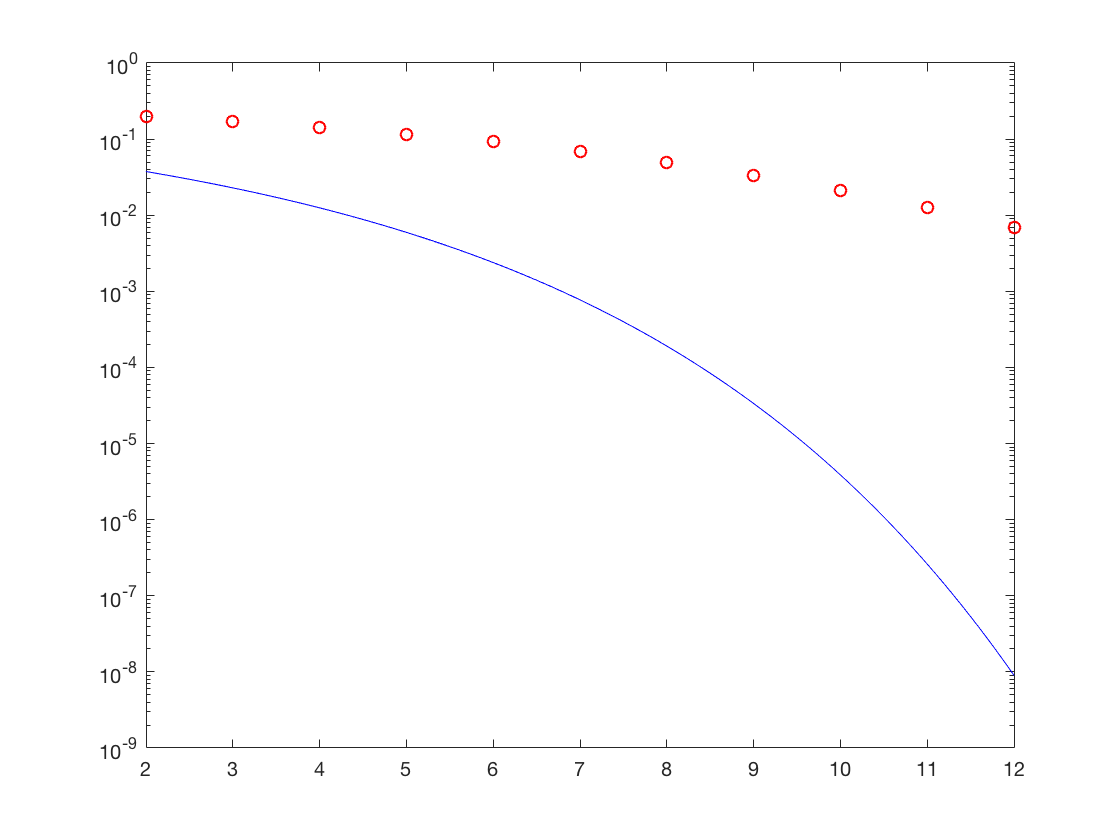

EbN0 = 2:0.1:12;
BER = 0.5*erfc(sqrt(10.^(EbN0/10)));
semilogy(EbN0, BER, 'b-')

Diagramma ad occhio

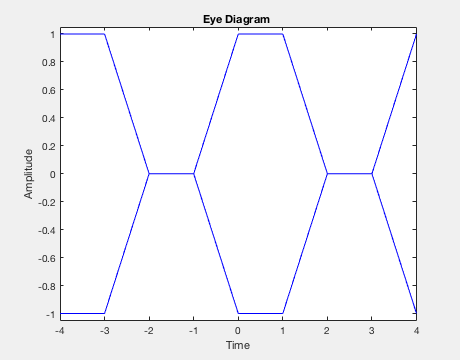

figure(3)
eyediagram(v_t(1:2000*SpS), 2*SpS, 2*SpS);

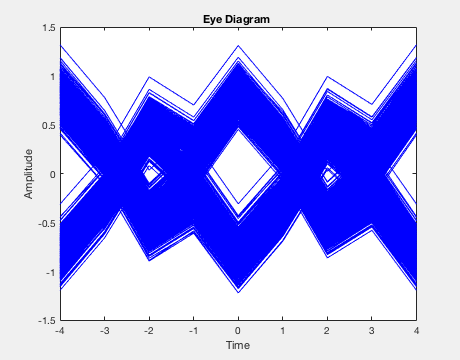



X_f_nn = fft(v_t);
Y_f_nn = H_rx .* X_f_nn;
y_nn = real(ifft(Y_f_nn));
figure(4)
eyediagram(y_nn(1:2000*SpS), 2*SpS, 2*SpS);